clc;clear;

**1. fsolve函数 **非线性方程组求解

有三种算法

**调用形式1 ：最基础的调用**

fun = @root2d;
x0 = [0,0];
x = fsolve(fun,x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


**调用形式2 使用非默认选项**

深入了解非线性方程组的求解过程。

将选项**设置为无显示和显示一阶最优性**的绘图函数，该函数应在算法迭代时收敛于 0。

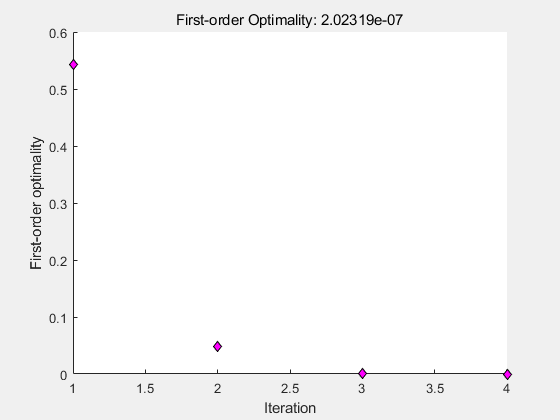

fun = @root2d;
x0 = [0,0];
options = optimoptions('fsolve','Display','none','PlotFcn',@optimplotfirstorderopt);
x = fsolve(fun,x0,options);

**调用形式3 求解参数化方程**

c = -1;%参数
fun = @(x)paramfun(x,c);%含参句柄
x0 = [0 1];
x = fsolve(fun,x0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =     0.1976    0.4255


**调用形式4 求解结构体问题**

x =     0.3532    0.6061


problem.options = optimoptions('fsolve','Display','none','PlotFcn',@optimplotfirstorderopt);
problem.objective = @root2d;%非线性方程组
problem.x0 = [0,0];
problem.solver = 'fsolve';
x = fsolve(problem)

**求解非线性方程组的过程**

F = @(x) [2*x(1) - x(2) - exp(-x(1));
         -x(1) + 2*x(2) - exp(-x(2))];
x0 = [-5;-5];
options = optimoptions('fsolve','Display','iter');
[x,fval] = fsolve(F,x0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3         47071.2                      2.29e+04               1
     1          6         12003.4              1       5.75e+03               1
     2          9         3147.02              1       1.47e+03               1
     3         12         854.452              1            388               1
     4         15         239.527              1            107               1
     5         18         67.0412              1           30.8               1
     6         21         16.7042              1           9.05               1
     7         24         2.42788              1           2.26               1
     8         27        0.032658       0.759511          0.206             2.5
     9         30     7.03149e-06       0.111927        0.00294             2.5
    10         33     3.29525e-13     0.001

x =     0.5671
    0.5671


fval = 1.0e-06 *

   -0.4059
   -0.4059


**验证解的可靠性的设置**

残差（fval） 

exitflag= 1 表示解是可靠的。

在 output 结构体中看到 fsolve 执行了多少次迭代和函数计算才求得解。

fun = @(x)x*x*x - [1,2;3,4];
x0 = ones(2);
options = optimoptions('fsolve','Display','off');
[x,fval,exitflag,output] = fsolve(fun,x0,options)%

x =    -0.1291    0.8602
    1.2903    1.1612


fval = 1.0e-11 *

   -0.3505    0.1633
    0.2417   -0.1111


exitflag = 1

output = 包含以下字段的 struct :
       iterations: 8
        funcCount: 41
        algorithm: 'trust-region-dogleg'
    firstorderopt: 5.1056e-12
          message: 'Equation solved.↵↵fsolve completed because the vector of function values is near zero↵as measured by the value of the function tolerance, and↵the problem appears regular as measured by the gradient.↵↵<stopping criteria details>↵↵Equation solved. The sum of squared function values, r = 2.202866e-23, is less than↵sqrt(options.FunctionTolerance) = 1.000000e-03. The relative norm of the gradient of r,↵5.105576e-12, is less than options.OptimalityTolerance = 1.000000e-06.'


sum(sum(fval.*fval))%计算残差（fval 的平方和），越接近零越好。

ans = 2.2029e-23

输入参数

输出参数

**2. ode45  偏微分方程求解**

**具有一个解分量的ODE**

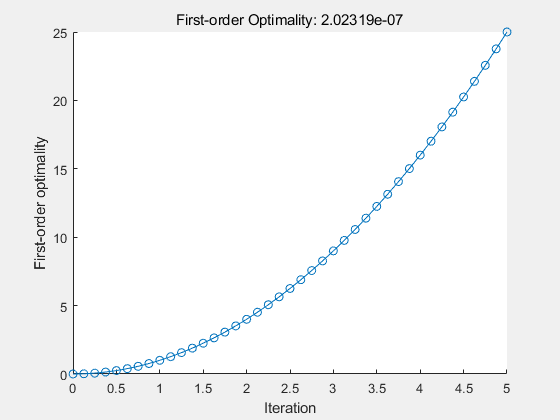

tspan = [0 5];%指定区间
y0 = 0;%指定初值
[t,y] = ode45(@(t,y) 2*t, tspan, y0);
plot(t,y,'-o')

**解算非刚性方程**

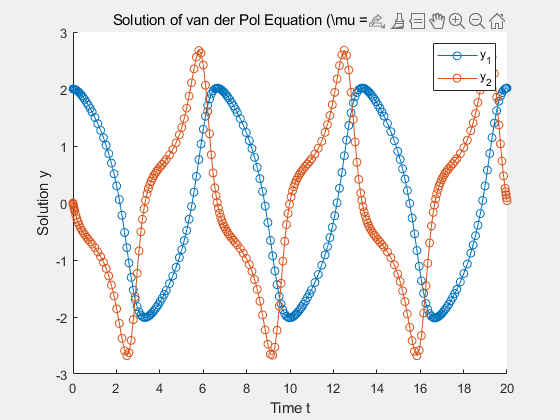

[t,y] = ode45(@vdp1,[0 20],[2; 0]);
plot(t,y(:,1),'-o',t,y(:,2),'-o')
title('Solution of van der Pol Equation (\mu = 1) with ODE45');
xlabel('Time t');
ylabel('Solution y');
legend('y_1','y_2')

**向 ODE 函数传递额外的参数**

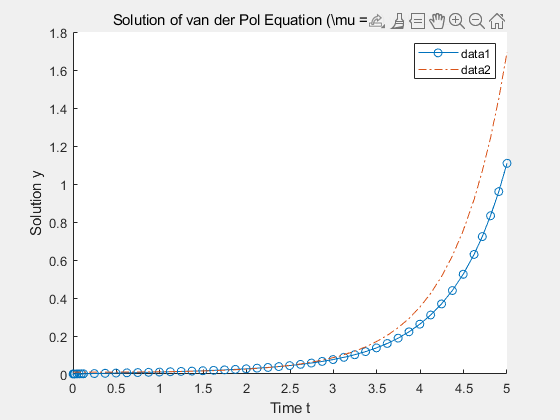

A = 1;
B = 2;
tspan = [0 5];
y0 = [0 0.01];
[t,y] = ode45(@(t,y) odefcn(t,y,A,B), tspan, y0);
plot(t,y(:,1),'-o',t,y(:,2),'-.')

**求解具有多个初始条件的 ODE**

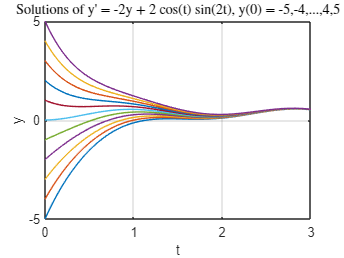

yprime = @(t,y) -2*y + 2*cos(t).*sin(2*t);
y0 = -5:5; 
tspan = [0 3];
[t,y] = ode45(yprime,tspan,y0);
plot(t,y)
grid on
xlabel('t')
ylabel('y')
title('Solutions of y'' = -2y + 2 cos(t) sin(2t), y(0) = -5,-4,...,4,5','interpreter','latex')

**带有时间依赖项的 ODE**

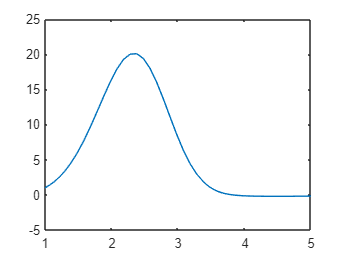

ft = linspace(0,5,25);
f = ft.^2 - ft - 3;
gt = linspace(1,6,25);
g = 3*sin(gt-0.25);
tspan = [1 5];
ic = 1;
opts = odeset('RelTol',1e-2,'AbsTol',1e-4);
[t,y] = ode45(@(t,y) myode(t,y,ft,f,gt,g), tspan, ic, opts);
plot(t,y)

**计算和扩展解结构体**

tspan = [0 20];
y0 = [2 0];
sol = ode45(@vdp1,tspan,y0)

sol = 包含以下字段的 struct :
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 1.0048e-04 6.0285e-04 0.0031 0.0157 0.0785 0.2844 0.5407 0.8788 1.4032 1.8905 2.3778 2.7795 3.1285 3.4093 3.6657 3.9275 4.2944 4.9013 5.3506 5.7998 6.2075 6.5387 6.7519 6.9652 7.2247 7.5719 8.1226 8.6122 9.1017 9.5054 9.8402 10.1157 … ]
          y: [2×60 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


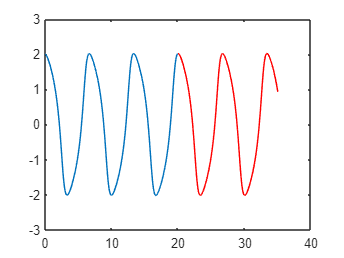

x = linspace(0,20,250);
y = deval(sol,x);
plot(x,y(1,:))
sol_new = odextend(sol,@vdp1,35);
x = linspace(20,35,350);
y = deval(sol_new,x);
hold on
plot(x,y(1,:),'r')